# The displacement vector field $u$

This 

## 1    The crystal lattice

For reference, shown here is an undistorted crystal lattice (basically a product of sinusoids) produced by substituting $\vec{u}=\vec{0}$ to equation S5 of Lawler-Fujita (2010)'s supplementary material.

Creating the lattice and applying the Fourier transform to the created image.

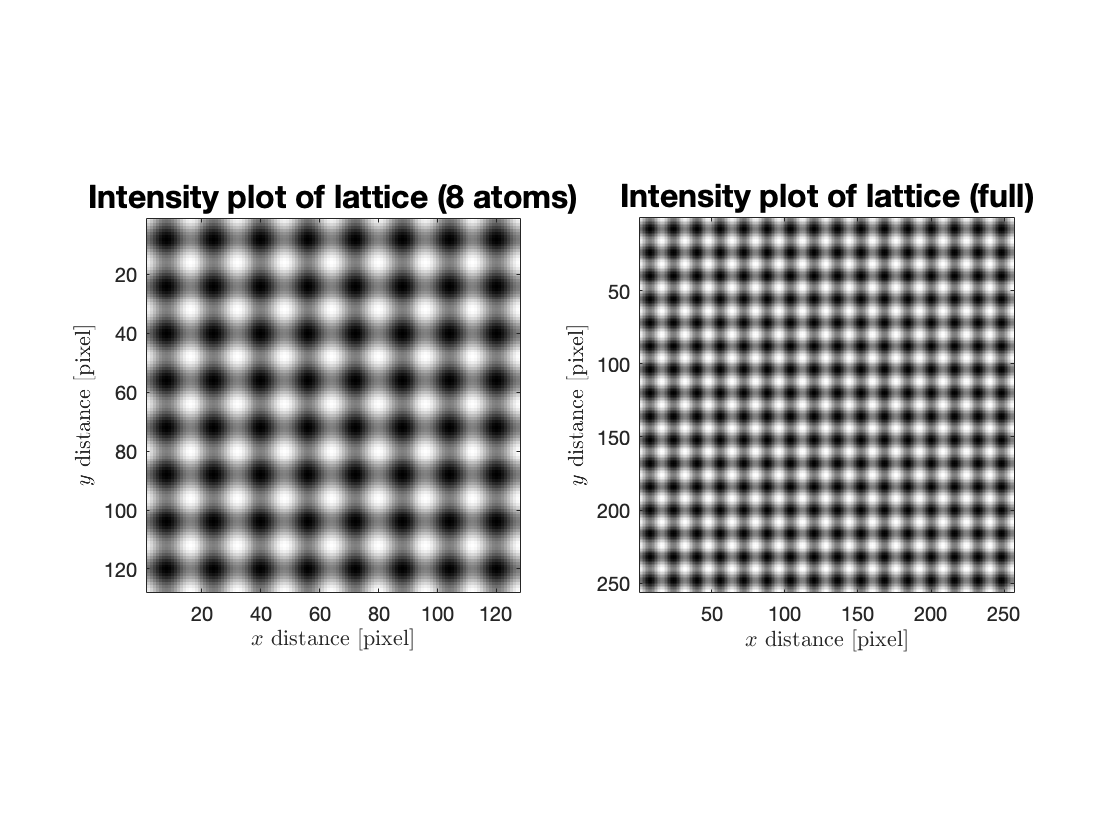

image_length = 256;
image_height = 256;
atom_diameter = 16;

Q_x = [1 0];
Q_y = [-Q_x(2) Q_x(1)]; % just to ensure orthogonality
Q_x = Q_x * 2*pi / (norm(Q_x)*atom_diameter);
Q_y = Q_y * 2*pi / (norm(Q_y)*atom_diameter);

lattice = normies(uTransform(uCreate(image_height,image_length,0) ...
    ,Q_x,Q_y)); % notice the zero
comboPlot(lattice,"lattice",atom_diameter);

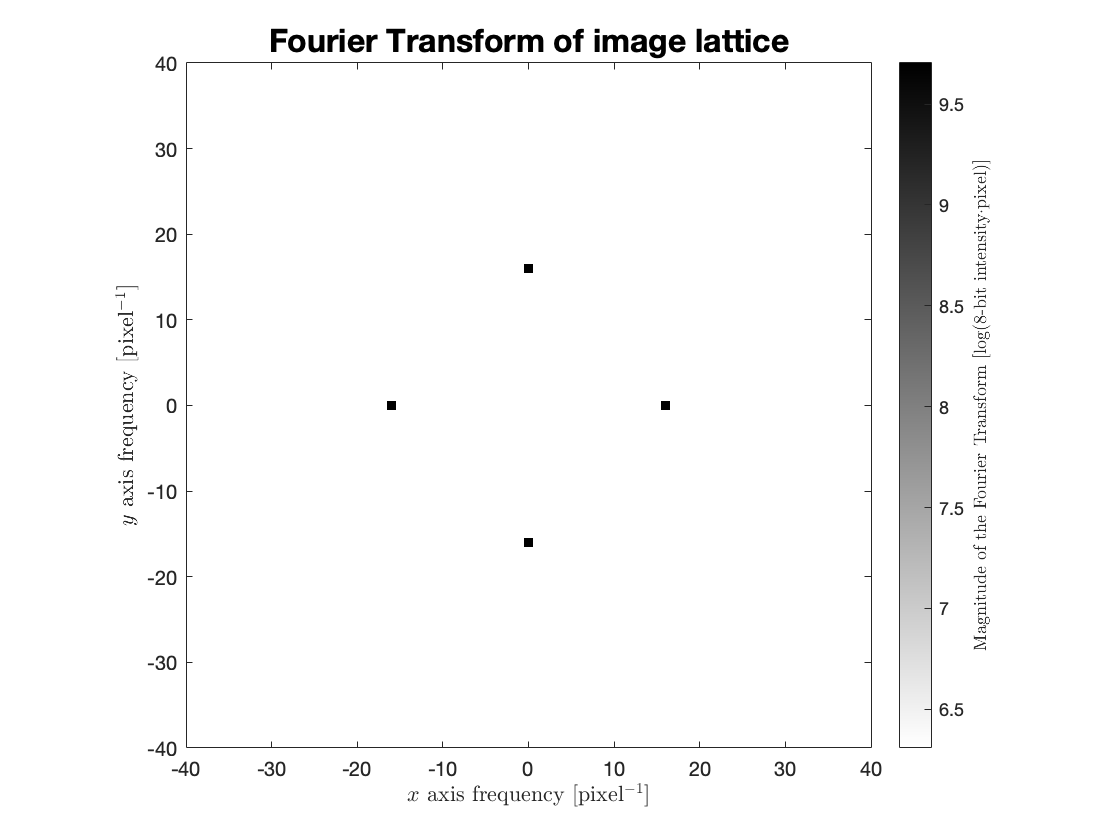

lattice_fft = myFFT(lattice,"lattice");

## 2    A distorted crystal lattice

We create a distorted lattice with the displacement vector [UNSPECIFIED] and apply the Fourier transform to the distorted image.

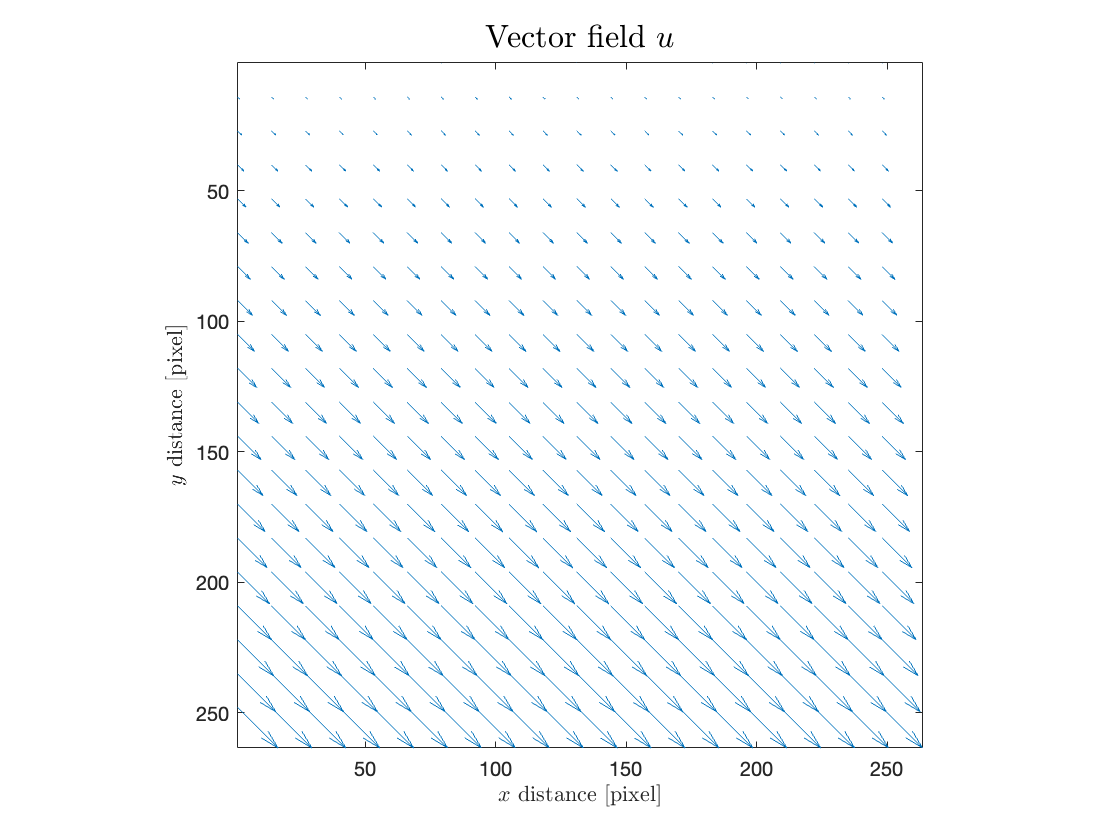

u = uCreate(image_height,image_length,image_height/atom_diameter);
% the last parameter just scales the magnitudes of the vectors in u
uPlot(u,"$u$");

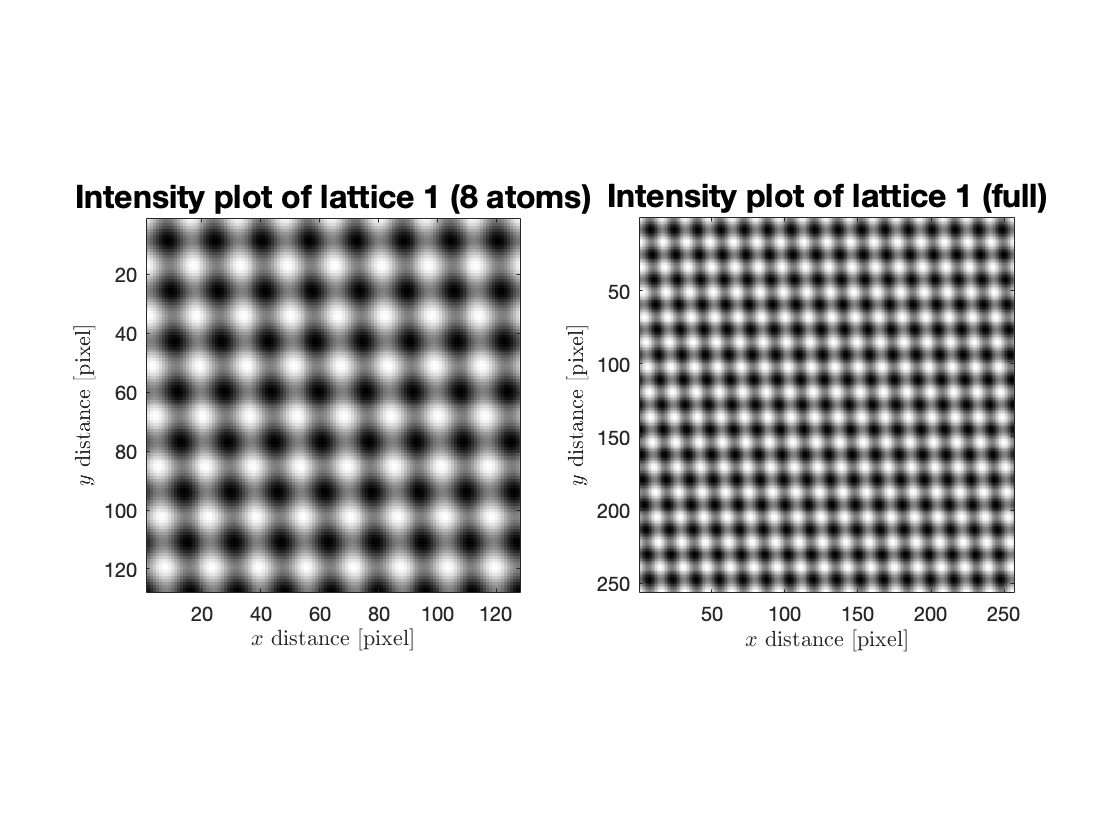


lattice1 = normies(uTransform(u,Q_x,Q_y));
comboPlot(lattice1,"lattice 1",atom_diameter);

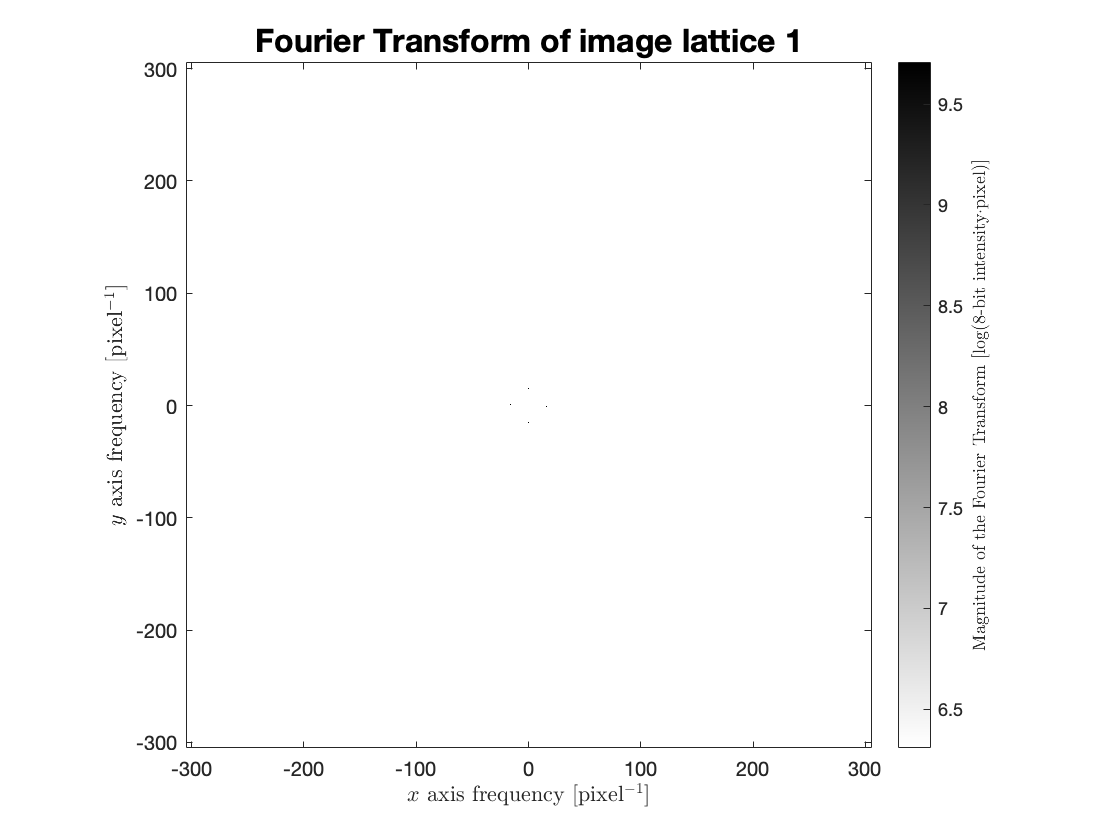


lattice1_fft = myFFT(lattice1,"lattice 1");

## 3    Calculating the vector field $u$

We're going to pretend that we don't know the displacement vector field that resulted to lattice1. Let's calculate $u$ only from the matrix/image lattice1.

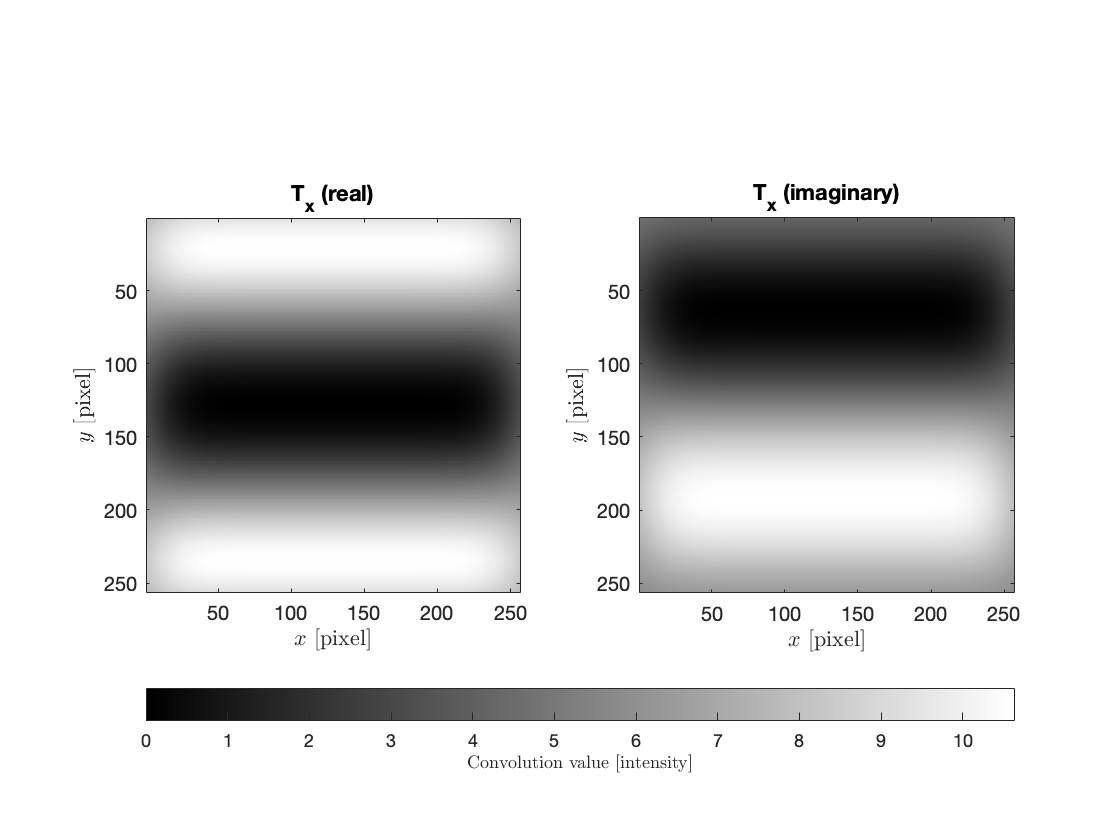

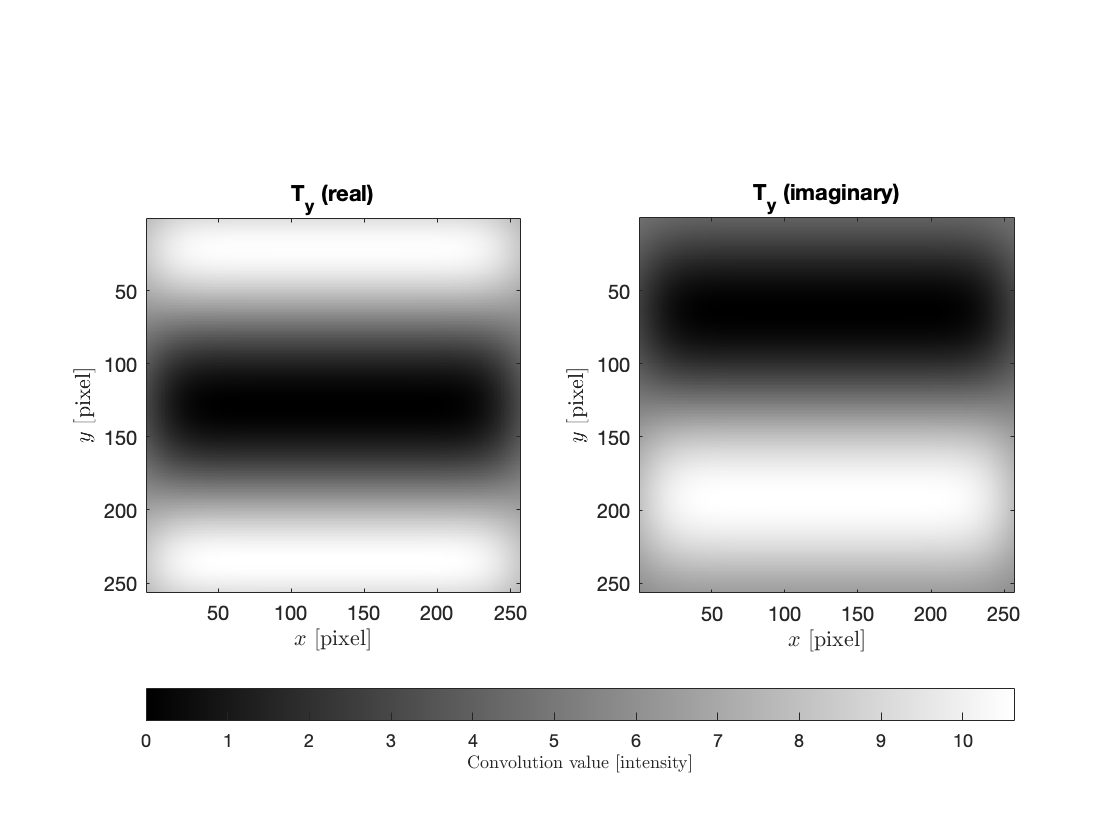

lambda = 0.05;

tic
ucalc = myConv(lattice1,Q_x,Q_y,lambda);

toc

Elapsed time is 0.897980 seconds.


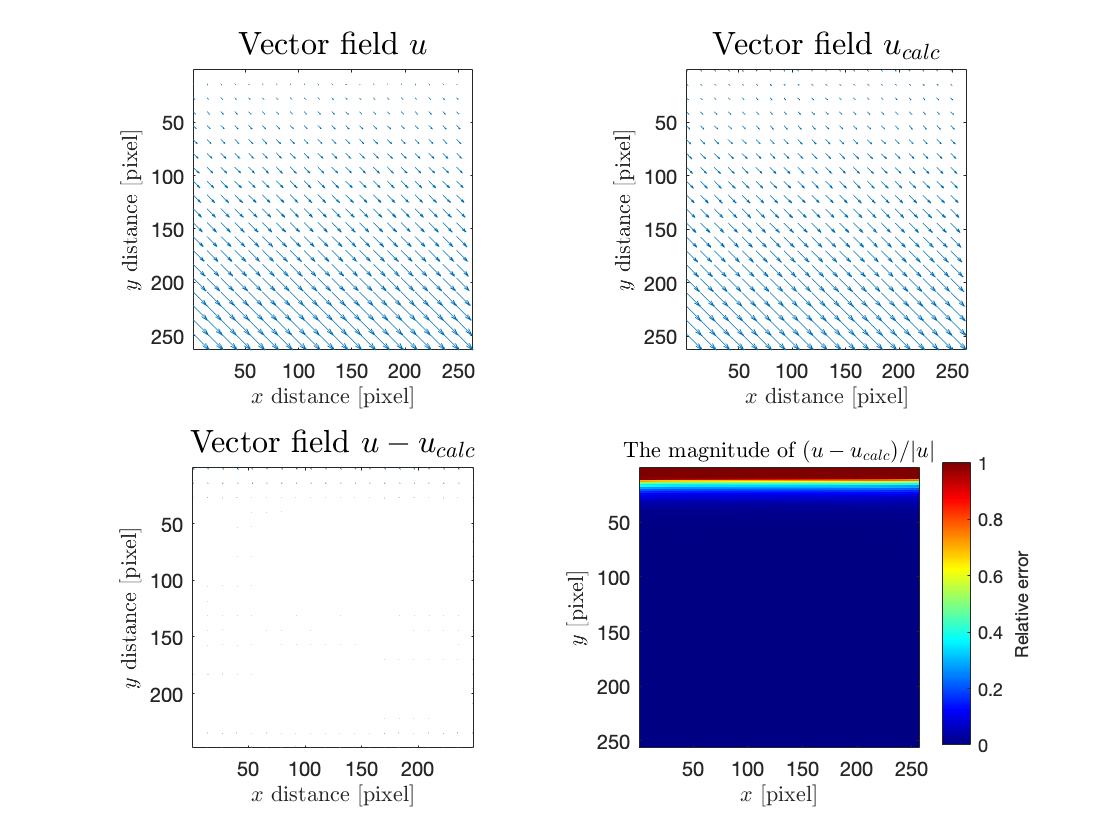


uComboPlot(u,ucalc);

Notice the wanky edges on the $T_x$ and $T_y$ plots. That's because the convolution function in MatLab padds the matrices with zeros on the edges.

## Functions

Included here are the list of parameters for every user-defined function in this directory that might be useful in this script.

#### The big ones

[Q, idx, idy] = myFFT(P, nm, dip) —* P is the image; nm is the title; dip=[0.65 1] [optional] sets the limits of the colorbar where 1 is the value of the second highest peak; Q is the fft; idx, idy are the indices of Qx, Qy*

**(!) **s = uCreate(h,l, scale_mag) —* s is the vector field; h, l are the matrix dimensions; scale_mag=15 [optional] scales the magnitudes of the vectors*

P = uTransform(s,qx,qy) —* P is the image matrixl s is the vector field; qx, qy are the lattice wavevectors*

blat = myConv(lat,qx,qy,lamb) —* blat is the vector field result of the convolution; lat is the image matrix; qx, qy are the lattice wavevectors; lamb is *$\Lambda_u$ in Lawler et al. (2010)'s supplementary information paper

#### Plotting

latticePlot(P0,nm1,r,num) — *P0 is the image (uint8); nm1 is the title; r [optional], num=8 [optional] specify the view*

comboPlot(P0, nm, a) — * P0 is the image (uint8); nm1 is the title; a is the atom diameter*

uPlot(s,nm) —* s is the vector field; nm is the title*

convPlot(lat,nm) —* lat is the image lattice; nm is the title*

uComboPlot(u,ucalc) —* u is the known vector field; ucalc is the calculated vector field*

#### Miscellaneous

A = normies(A, lim) —* A is the matrix; lim=[-1 1] [optional] are the limits*

#### Local

function s = uCreate(h,l, scale_mag)
    s = zeros(h,l,2);
    scale_coor = 1; % to scale the coordinates of the vector field
    if nargin<3
        scale_mag = 15; % to scale the magnitude of the vectors in the vector field
    end
    
    % create x and y for spatial dependence
    [x,y] = meshgrid(1:l,1:h);
    x = scale_coor.*x./l;
    y = scale_coor.*y./h;
    
    %create t for temporal dependence (like raster scan)
    t = 1:h*l;
    t = reshape(t,[l h])';
    t(2:2:end,:) = fliplr(t(2:2:end,:));
    
    % change these to change the vector field u
    s(:,:,1) = t/(h*l)*scale_mag;
    s(:,:,2) = t/(h*l)*scale_mag;
    
%     uPlot(s,"$u$");
end